**Time Domain Analysis of Second Order system with different values of **$\zeta$**to a unit step input**

 
syms t s real
syms wn positive

Critically Damped  System 


$$sys=\frac{wn^2}{s(s^2+2 wns+wn^2)}$$


sys1=wn^2/(s*(s^2+2*wn*s+wn^2));
inv_sys=ilaplace(sys1,s,t)

$$inv\_sys = 1-t\,\mathrm{wn}\,{\mathrm{e}}^{-t\,\mathrm{wn}}-{\mathrm{e}}^{-t\,\mathrm{wn}}$$

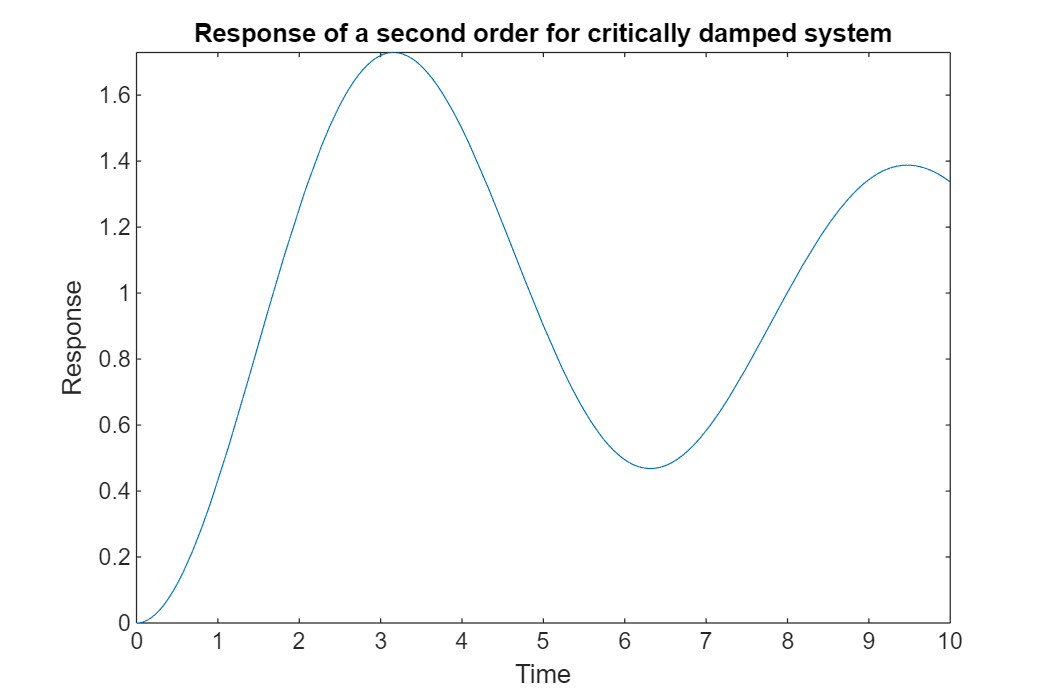

inv_sys=subs(inv_sys,[wn],[1]);
fplot(inv_sys);
title("Response of a second order for critically damped system")
ylabel("Response")
xlabel("Time")
xlim([0,10])

Underdamped Damped  System 


$$sys=\frac{wn^2}{s(s^2+0.2 wns+wn^2)}$$


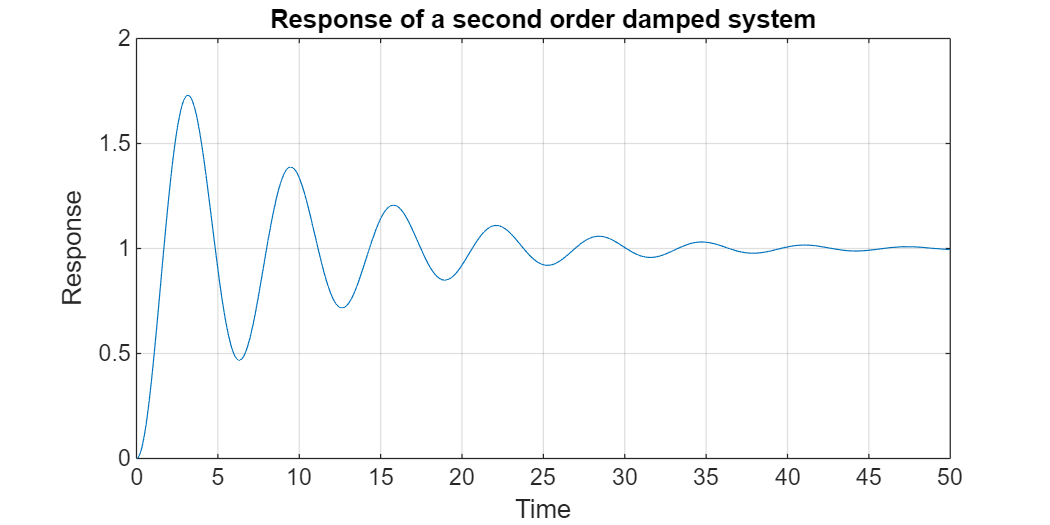

figure(position=[0,0,600,300])
sys2=wn^2/(s*(s^2+2*0.1*wn*s+wn^2));
inv_sys=ilaplace(sys,s,t);
fplot(subs(inv_sys,[wn],[1]));
title("Response of a second order damped system")
ylabel("Response")
xlabel("Time")
xlim([0,50])
ylim([0,2])
grid on 

xlim([0.0 50.0])
ylim([0.00 2.00])

Using Step function in matlab to do this analsysis with Ease.

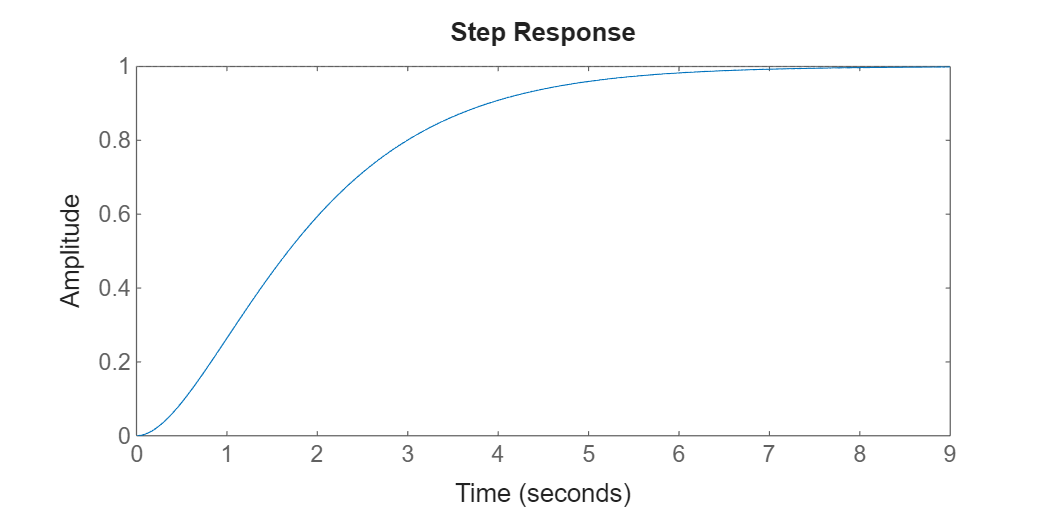

sys1=tf([1],[1,2,1]);
step(sys1)

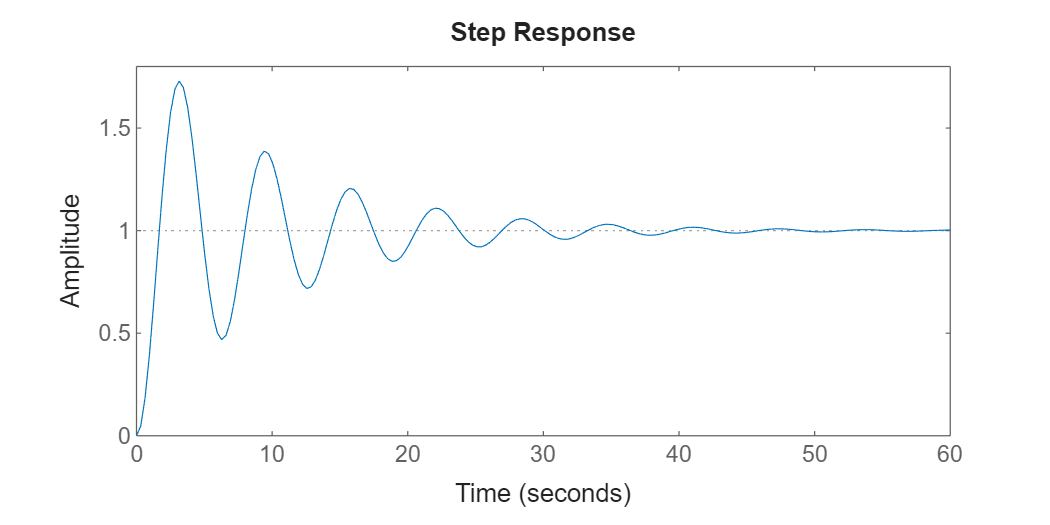

sys2=tf([1],[1,0.2,1]);
step(sys2)

stepinfo(sys1)

ans = struct with fields:
         RiseTime: 3.3579
    TransientTime: 5.8339
     SettlingTime: 5.8339
      SettlingMin: 0.9000
      SettlingMax: 0.9994
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9994
         PeakTime: 9.7900


stepinfo(sys2)

ans = struct with fields:
         RiseTime: 1.1272
    TransientTime: 38.3730
     SettlingTime: 38.3730
      SettlingMin: 0.4685
      SettlingMax: 1.7292
        Overshoot: 72.9156
       Undershoot: 0
             Peak: 1.7292
         PeakTime: 3.1416


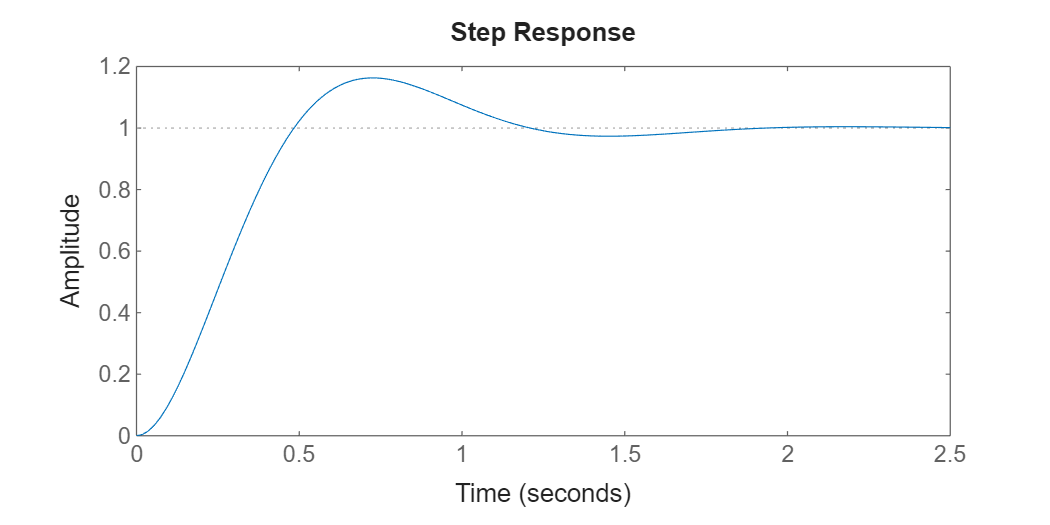

sys=tf([25],[1,5,25]);
step(sys)

stepinfo(sys)

ans = struct with fields:
         RiseTime: 0.3278
    TransientTime: 1.6152
     SettlingTime: 1.6152
      SettlingMin: 0.9315
      SettlingMax: 1.1629
        Overshoot: 16.2929
       Undershoot: 0
             Peak: 1.1629
         PeakTime: 0.7184


% =========================================================================
% Second-Order System Simulation: Mass-Spring-Damper
% =========================================================================
clear; clc; close all;

% 1. Define Physical Parameters
m = 1000;    % Mass (e.g., quarter of a 1000kg car body) in kg
k = 40000;   % Spring constant in N/m
c = 8000;    % Damping coefficient in N-s/m

% 2. Calculate Derived Second-Order Parameters
omega_n = sqrt(k / m);              % Natural frequency (rad/s)
zeta = c / (2 * sqrt(k * m));       % Damping ratio

fprintf('--- System Properties ---\n');

--- System Properties ---


fprintf('Natural Frequency (\x03C9n): %.2f rad/s (%.2f Hz)\n', omega_n, omega_n/(2*pi));

Natural Frequency (ωn): 6.32 rad/s (1.01 Hz)


fprintf('Damping Ratio (\x03B6): %.2f\n\n', zeta);

Damping Ratio (ζ): 0.63



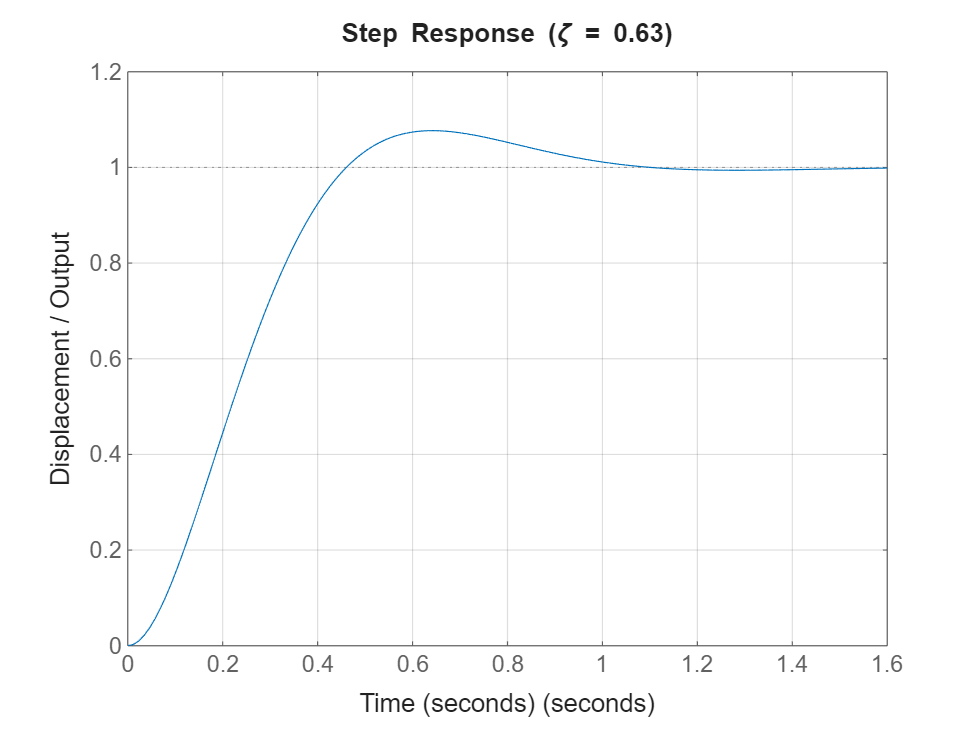


% 3. Create the Transfer Function: G(s) = (k/m) / (s^2 + (c/m)s + k/m)
num = [k/m];
den = [1, c/m, k/m];
G = tf(num, den);

% 4. Run Step Response Test
figure;
step(G);
grid on;
title(sprintf('Step Response (\\zeta = %.2f)', zeta));
xlabel('Time (seconds)');
ylabel('Displacement / Output');


% 5. Extract and Display Performance Metrics Automatically
info = stepinfo(G);
fprintf('--- Test Performance Metrics ---\n');

--- Test Performance Metrics ---


fprintf('Rise Time (tr): %.3f seconds\n', info.RiseTime);

Rise Time (tr): 0.306 seconds


fprintf('Settling Time (ts): %.3f seconds\n', info.SettlingTime);

Settling Time (ts): 0.948 seconds


fprintf('Overshoot (Mp): %.2f%%\n', info.Overshoot);

Overshoot (Mp): 7.69%


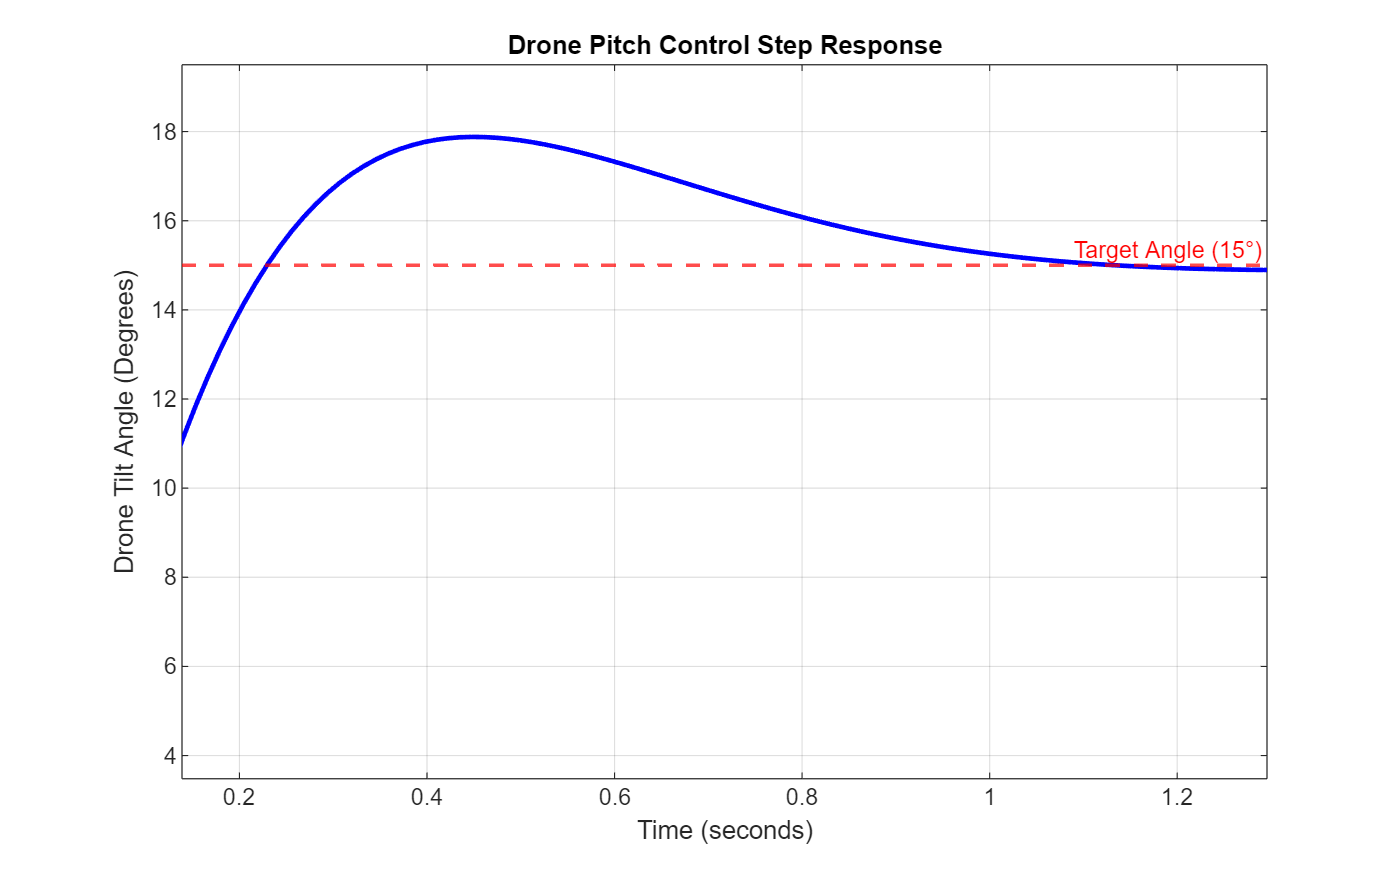

% =========================================================================
% Drone Pitch/Roll Angle Control Simulator
% =========================================================================
clear; clc; close all;

% 1. Physical Parameters of the Drone
I = 0.05;      % Rotational Inertia of a small quadcopter (kg*m^2)
b = 0.01;      % Aerodynamic aerodynamic drag (N-m-s/rad)

% Drone Plant Transfer Function: Gp(s) = 1 / (I*s^2 + b*s)
num_drone = [1];
den_drone = [I, b, 0];
Gp = tf(num_drone, den_drone);

% 2. Design the Virtual "Spring" and "Damper" (PID Controller Tunings)
% We want a fast response with a damping ratio (zeta) of ~0.707
Kp = 1.25;     % Proportional Gain (Virtual Spring Stiffness)
Kd = 0.35;     % Derivative Gain (Virtual Shock Absorber Damping)

% Controller Transfer Function: C(s) = Kd*s + Kp
num_controller = [Kd, Kp];
den_controller = [1];
C = tf(num_controller, den_controller);

% 3. Build the Closed-Loop System
% T_loop(s) = (C * Gp) / (1 + C * Gp)
Loop_Forward = series(C, Gp);
T_loop = feedback(Loop_Forward, 1);

% 4. Test the Drone: Step Input of 15 Degrees Target Tilt
target_angle = 15; % degrees
[angle_output, time] = step(target_angle * T_loop);

% 5. Plot the Flight Test Simulation Results
figure('Position', [100, 100, 800, 500]);
plot(time, angle_output, 'b-', 'LineWidth', 2);
hold on;
yline(target_angle, 'r--', 'Target Angle (15°)', 'LineWidth', 1.5);
grid on;

title('Drone Pitch Control Step Response');
xlabel('Time (seconds)');
ylabel('Drone Tilt Angle (Degrees)');
ylim([0, target_angle * 1.3]); % Scale axis to view overshoot


% 6. Display Metrics
info = stepinfo(target_angle * T_loop);
fprintf('--- Drone Performance Flight Data ---\n');

--- Drone Performance Flight Data ---


fprintf('Rise Time (Time to tilt): %.3f seconds\n', info.RiseTime);

Rise Time (Time to tilt): 0.174 seconds


fprintf('Settling Time (Time to stabilize): %.3f seconds\n', info.SettlingTime);

Settling Time (Time to stabilize): 0.985 seconds


fprintf('Overshoot (Angle wobble): %.2f%%\n', info.Overshoot);

Overshoot (Angle wobble): 19.20%


% =========================================================================
% Quick Drone Visualizer (Run this in a standard MATLAB script)
% =========================================================================
clear; clc; close all;

% Simulate a simple oscillating drone pitch angle over 3 seconds
t = 0:0.05:3;
simulated_angles = 15 * (1 - exp(-2*t).*cos(10*t)); % Simulated underdamped tilt

figure('Name', 'Drone Live Tilt Visualizer');
grid on;

% Animation Loop
for i = 1:length(t)
    theta = deg2rad(simulated_angles(i)); % Convert to radians
    
    % Define the physical ends of the drone frame (X-axis)
    arm_length = 0.5; 
    x_front = arm_length * cos(theta);
    y_front = arm_length * sin(theta);
    x_rear  = -arm_length * cos(theta);
    y_rear  = -arm_length * sin(theta);
    
    % Plot the drone body frame line
    plot([x_rear, x_front], [y_rear, y_front], 'b-o', 'LineWidth', 4, 'MarkerSize', 10);
    hold on;
    % Draw a red "Front" indicator prop
    plot(x_front, y_front, 'ro', 'MarkerSize', 15, 'LineWidth', 3); 
    hold off;
    
    % Format the viewing window
    axis([-1 1 -1 1]);
    grid on;
    title(sprintf('Time: %.2fs | Current Tilt Angle: %.1f°', t(i), simulated_angles(i)));
    xlabel('Horizontal Distance');
    ylabel('Vertical Distance');
    
    drawnow; % Forces MATLAB to update the screen instantly
    pause(0.05); % Match the time step for real-time viewing
end